# Problema 2

## Formula trapezului

%PB1
function integral = integrare_trapeze(f, a, b, divizari)
    % Calculeaza integrala aproximativa a lui f pe [a,b]
    % folosind formula trapezelor compusă cu 'divizari' subintervale

    pas = (b - a) / divizari; % pasul intre noduri
    puncte = linspace(a, b, divizari + 1); % genereaza nodurile: x0, x1, ..., xn
    valori = arrayfun(f, puncte); % evalueaza functia in fiecare nod

    % Aplica formula trapezului:
    integral = pas * (sum(valori) - 0.5 * (valori(1) + valori(end)));
end


## Formula lui Simpson

%PB1
function integral = integrare_simpson(f, a, b, divizari)
    % Calculeaza integrala aproximativa a lui f pe [a,b]
    % folosind regula compusă a lui Simpson cu 'divizari' subintervale (n = par)

    if rem(divizari, 2) ~= 0
        error('divizari trebuie sa fie par pentru regula Simpson.');
    end

    pas = (b - a) / divizari; % pasul intre noduri
    puncte = a + (0:divizari) * pas; % nodurile x0, x1, ..., xn
    valori = f(puncte); % evaluarea functiei in fiecare nod

    % Coeficienții:
    coef4 = sum(valori(2:2:end-1));
    coef2 = sum(valori(3:2:end-2));

    % Formula Simpson compusa:
    integral = pas/3 * (valori(1) + 4 * coef4 + 2 * coef2 + valori(end));
end

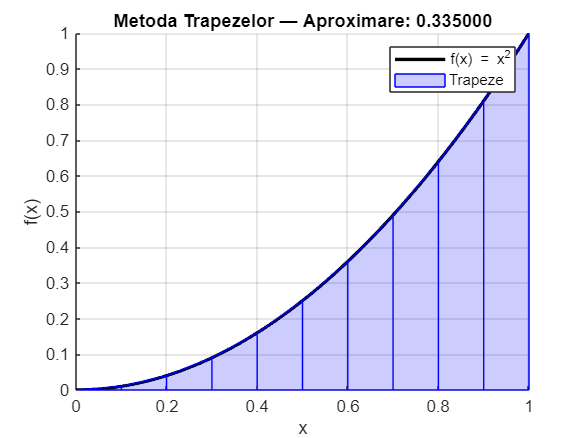

% === PREGATIRE PENTRU GRAFIC ===
n = 10; % trebuie sa fie par pentru Simpson
h = (b - a) / n;
x_fine = linspace(a, b, 1000);
y_fine = f(x_fine);
x_nodes = linspace(a, b, n + 1);
y_nodes = f(x_nodes);
x_mijloc = (x_nodes(1:end-1) + x_nodes(2:end)) / 2;
y_mijloc = f(x_mijloc);

% === FIGURA 1: Trapeze ===
figure;
hold on;
plot(x_fine, y_fine, 'k', 'LineWidth', 2);
for i = 1:n
    x_trap = [x_nodes(i), x_nodes(i), x_nodes(i+1), x_nodes(i+1)];
    y_trap = [0, y_nodes(i), y_nodes(i+1), 0];
    fill(x_trap, y_trap, 'b', 'FaceAlpha', 0.2, 'EdgeColor', 'b');
end
title(sprintf('Metoda Trapezelor — Aproximare: %.6f', rez_trapeze));
legend('f(x) = x^2', 'Trapeze');
xlabel('x'); ylabel('f(x)');
grid on;
hold off;

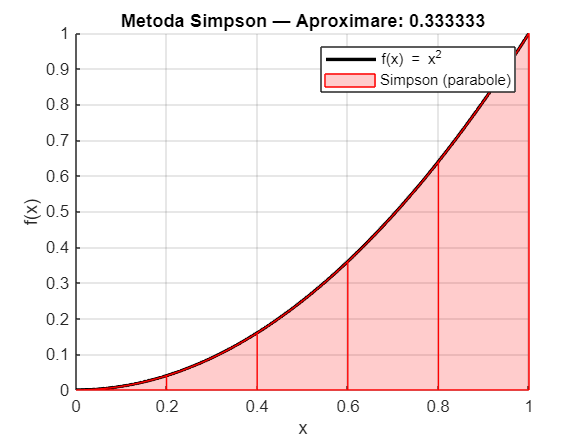


% === FIGURA 3: Simpson ===
figure;
hold on;
plot(x_fine, y_fine, 'k', 'LineWidth', 2);
for i = 1:2:n-1
    x_parab = linspace(x_nodes(i), x_nodes(i+2), 100);
    y_parab = f(x_parab);
    fill([x_parab, fliplr(x_parab)], [y_parab, zeros(size(y_parab))], ...
        'r', 'FaceAlpha', 0.2, 'EdgeColor', 'r');
end
title(sprintf('Metoda Simpson — Aproximare: %.6f', rez_simpson));
legend('f(x) = x^2', 'Simpson (parabole)');
xlabel('x'); ylabel('f(x)');
grid on;
hold off;